img = imread('test_images/infected/C33P1thinF_IMG_20150619_114756a_cell_179.png');
%img = imread('test_images/NotInfected/C1_thinF_IMG_20150604_104722_cell_115.png');
%img = imread('C33P1thinF_IMG_20150619_121435a_cell_173.png');
grayimg = rgb2gray(img);
%montage({img,grayimg});title('RGB       vs          Gray image')

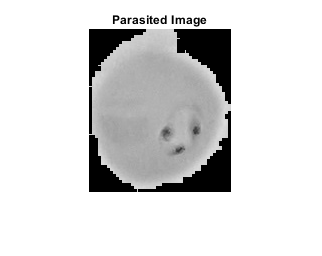

imshow(grayimg);title('Parasited Image');

%montage({grayimg,edge(grayimg,'approxcanny'),edge(grayimg,'canny'),edge(grayimg,'canny_old'),edge(grayimg,'log'),edge(grayimg,'prewitt',0.05),edge(grayimg,'roberts',0.05),edge(grayimg,'sobel',0.05)},Size=[3,3]);

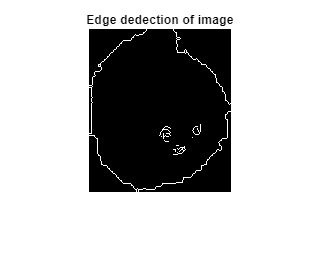

edgeimg = edge(grayimg,'sobel',0.05);
imshow(edgeimg);title('Edge dedection of image');

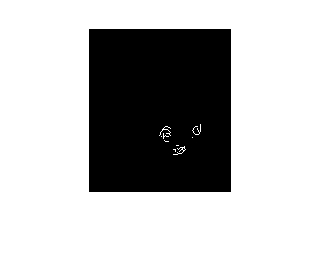

sites_img = edge(grayimg,'sobel',0.05)-edge(grayimg,'sobel');
imshow(sites_img);

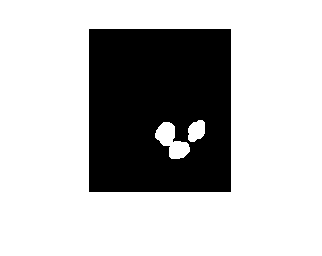

sites_img = imdilate(sites_img,strel('disk',5));
imshow(sites_img);

region_stats = regionprops(sites_img,grayimg,"Area","BoundingBox")

region_stats = struct with fields:
           Area: 973
    BoundingBox: [66.5000 91.5000 50 39]


sum(region_stats.Area)

ans = 973

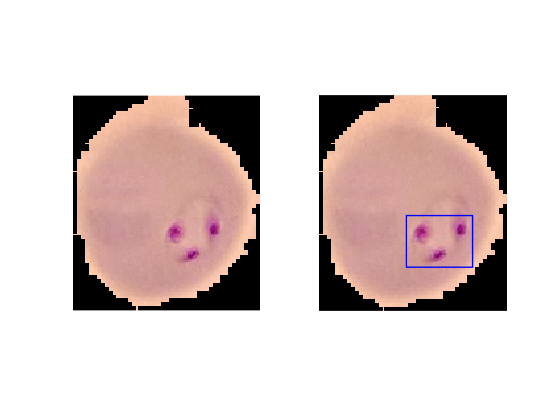

figure(4)
subplot(1,2,1);imshow(img);
subplot(1,2,2);imshow(img);hold on
rectangle('Position', region_stats.BoundingBox,'EdgeColor','b', 'LineWidth', 1)
saveas(gcf,'profile.png')

%text(x, y, 'This is my rectangle', 'FontSize', 20);

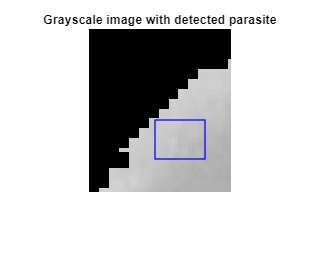

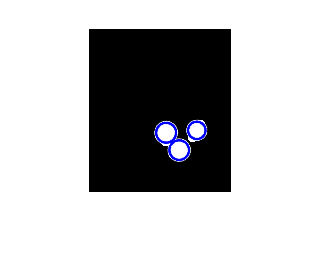

% [centers,radii] = imfindcircles(sites_img,[6, 40]);

% viscircles(centers,radii,'EdgeColor','b');

% CC = bwconncomp(grayimg)
% numPixels = cellfun(@numel,CC.PixelIdxList);
% [biggest,idx] = max(numPixels);
% grayimg(CC.PixelIdxList{idx}) = 0;
% imshow(grayimg)

L = bwlabel(edgeimg,4);

centers =    51.7725   62.6103
   45.1756   58.3087
   76.4399   15.5604
   91.0231   33.6813


radii =     7.9121
    7.4456
   12.7261
   10.4438


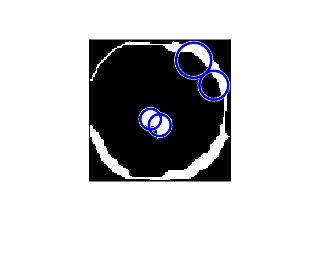

bwareaopen(grayimg)

Error using bwareaopen>parse_inputs (line 82)
Not enough input arguments.

Error in bwareaopen (line 65)
[bw,p,conn] = parse_inputs(varargin{:});